syms y(x)
y(x) = cos(x)^2

$$y(x) = {\cos\left(x\right)}^{2}$$

부정적분 구하기: $Y(x)=\int y(x) dx$

Y = int(y, x)

$$Y(x) = \frac{x}{2}+\frac{\sin\left(2\,x\right)}{4}$$

정적분으로 면적 구하기: $A=\int_{0}^{\pi/4} y(x) dx$

A = int(y, [0 pi/4])

$$A = \frac{\pi }{8}+\frac{1}{4}$$

double(A)

ans = 0.6427

그래프

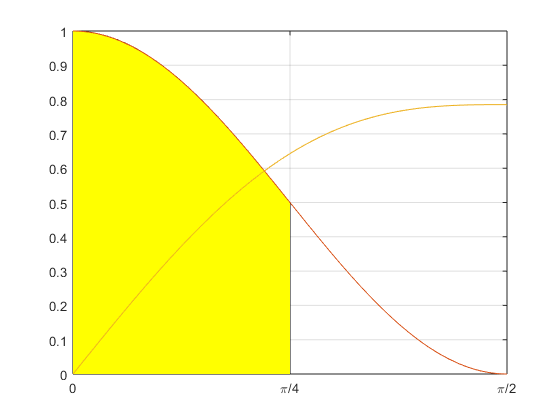

x1 = linspace(0, pi/4, 100);
p = patch([x1 pi/4 0 0], [double(y(x1)) 0 0 1], 'y');
xlim([0, pi/2]); p.LineStyle = 'none';
hold on;
h = fplot([y Y], [0, 0.5*pi]);
a = gca; a.XTick = pi*(0:0.25:0.5);
a.XTickLabel=["0", "\pi/4", "\pi/2"];
grid on; hold off;

적분 구간이 $\infty$를 포함하는 경우: $\int_{-\infty}^{\infty} e^{-x^2} dx$

int(exp(-x^2),[-inf, inf])

$$ans = \sqrt{\pi }$$

그래프

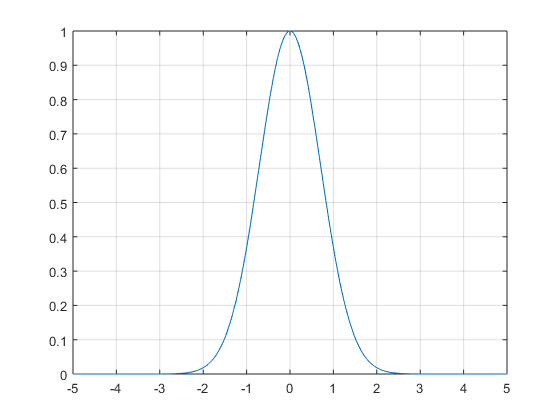

fplot(exp(-x^2))
grid on;

부정적분 결과를 수식으로 표현하지 못하는 경우

z = int(x*exp(-cos(x)^2), [0 1])

$$z = \int_{0}^{1}x\,{\mathrm{e}}^{-{\cos\left(x\right)}^{2}}\mathrm{d}x$$

이 경우 수치값을 구할 수 있음

double(z)

ans = 0.2799

그래프

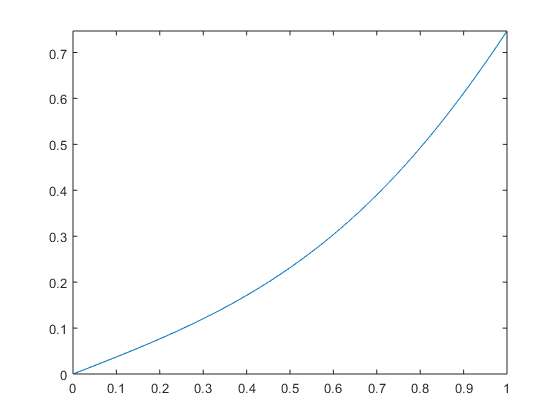

fplot(x*exp(-cos(x)^2), [0 1])